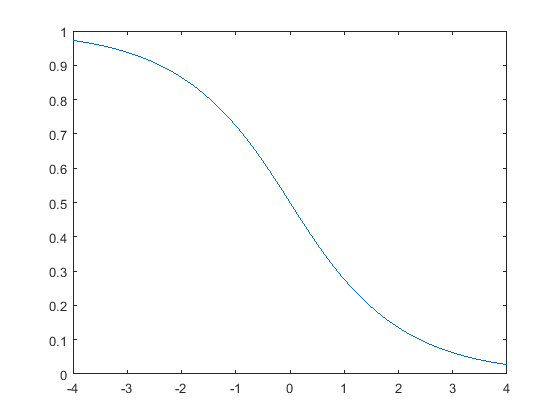

clear

x = linspace(-4, 4);
y = expon(x, 1);
% hold on 
plot(x, y);

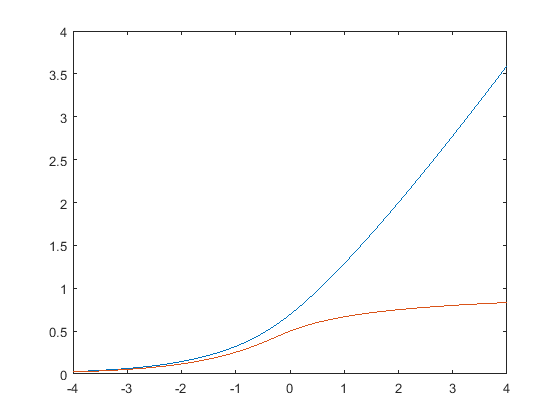

plot(x, -log(y));
hold on
yd = expon_nlog_d(x, 1);
plot(x, yd);


% func = @(x) expon_d(x, 1);
% integral(func, -10, 10)

syms x gamma
pos = 1/4*exp(-gamma.*x).*(gamma.*x+2) %% 

$$pos = \frac{{\mathrm{e}}^{-\gamma \,x}\,\left(\gamma \,x+2\right)}{4}$$

% pos_d = diff(pos)
% pos_d_gamma = simplify(diff(pos, gamma))
pos_d_nlog = simplify(diff(-log(pos))) % negative log likelihood

$$pos\_d\_nlog = \frac{\gamma \,\left(\gamma \,x+1\right)}{\gamma \,x+2}$$

pos_d_gamma_nlog = simplify(diff(-log(pos), gamma))

$$pos\_d\_gamma\_nlog = \frac{x\,\left(\gamma \,x+1\right)}{\gamma \,x+2}$$

pv = gamma.*(gamma*x+1)./(gamma*x+2)

$$pv = \frac{\gamma \,\left(\gamma \,x+1\right)}{\gamma \,x+2}$$

diff_pv = simplify(pv - pos_d_nlog)

$$diff\_pv = 0$$

syms x gamma
neg = 1/4*exp(gamma.*x).*(gamma.*x-2)+1 %% 

$$neg = \frac{{\mathrm{e}}^{\gamma \,x}\,\left(\gamma \,x-2\right)}{4}+1$$

% neg_d = diff(neg)
% neg_d_gamma = simplify(diff(neg, gamma))
neg_d_nlog = simplify(diff(-log(neg)))

$$neg\_d\_nlog = -\frac{\frac{\gamma \,{\mathrm{e}}^{\gamma \,x}}{4}+\frac{\gamma \,{\mathrm{e}}^{\gamma \,x}\,\left(\gamma \,x-2\right)}{4}}{\frac{{\mathrm{e}}^{\gamma \,x}\,\left(\gamma \,x-2\right)}{4}+1}$$

neg_d_gamma_nlog = simplify(diff(-log(neg), gamma))

$$neg\_d\_gamma\_nlog = -\frac{\frac{x\,{\mathrm{e}}^{\gamma \,x}}{4}+\frac{x\,{\mathrm{e}}^{\gamma \,x}\,\left(\gamma \,x-2\right)}{4}}{\frac{{\mathrm{e}}^{\gamma \,x}\,\left(\gamma \,x-2\right)}{4}+1}$$

nv = -gamma.*exp(gamma*x).*(gamma*x -1)./(exp(gamma.*x).*(gamma*x -2) + 4);
diff_nv = simplify(nv - neg_d_nlog)

$$diff\_nv = 0$$

function tot=expon(x, gamma)
    pos = 1/4 * exp(-gamma.*x).*(gamma.*x+2);
    neg = 1/4 * exp( gamma.*x).*(gamma.*x-2)+1;
    tot = (sign(x) + 1)/2.*pos + (sign(x) - 1)/(-2).*neg;             
end

function grad=expon_nlog_d(x, gamma)
    pv = gamma.*(gamma*x+1)./(gamma*x+2);
    nv = -gamma.*exp(gamma*x).*(gamma*x -1)./(exp(gamma.*x).*(gamma*x -2) + 4);
    tot = (sign(x) + 1)/2.*pv + (sign(x) - 1)/(-2).*nv; 
    grad = tot;
end